# Example Model: Counting Steps and Creating Graphics

*Copyright 2018 The MathWorks, Inc*

By now you should know how to collect data and save it to MATLAB Drive. Now we need to develop a model to take this data and output the desired data we want. This section will take you through making an example model to convert GPS data to steps taken. Remember **this is an example** and should only be used to help guide you to making your own model. And while this is how we calculate steps taken there are many other ways to do the same thing and we encourage that you try other ways to solve this same problem

## Preparing Data

To work with the data we must first load it into the workspace and store the variables that are going to be used in this example. While we can double click on the data to load it we use the load command to make this process easier to replicate.

clear
load('ExampleData.mat');
lat=Position.latitude;
lon=Position.longitude;
positionDatetime=Position.Timestamp;

Xacc = Acceleration.X;
Yacc = Acceleration.Y;
Zacc = Acceleration.Z;
accelDatetime=Acceleration.Timestamp;

% We use the following to obtain linear time data in seconds from a datetime array

positionTime=timeElapsed(positionDatetime);
accelTime=timeElapsed(accelDatetime);

## Determining Approach Method

Let’s say that you wanted to track the number of steps taken. One way that this can be done is by calculating the total distance traveled and then dividing it by your stride length. This works because stride is the distance taken for one step so if we look at the units they cancel out as seen below.

     
$$\frac{\textrm{totalDistance}\left(\textrm{ft}\right)}{\textrm{stride}\left(\frac{\textrm{ft}}{\textrm{step}}\right)}=\frac{\textrm{ft}}{\frac{\textrm{ft}}{\textrm{step}}}=\textrm{ft}*\frac{\textrm{step}}{\textrm{ft}}=\textrm{steps}$$


Not that we have an equation, the next step is to solve it MATLAB. The first step is to get the total distance traveled which is done using data from your GPS location or the latitude and longitude sensor data. One way that we can solve this is by looking at your start location and end location and calculating the distance between those points. If we did that with the figure below the distance traveled would be 300ft because the start and end position is 3 squares apart. We can see that the person traveled much further than this however so we must calculate the distance along the path using each data point. In doing this the person below would’ve traveled 1500ft which is a large difference from the 300ft first calculated.

 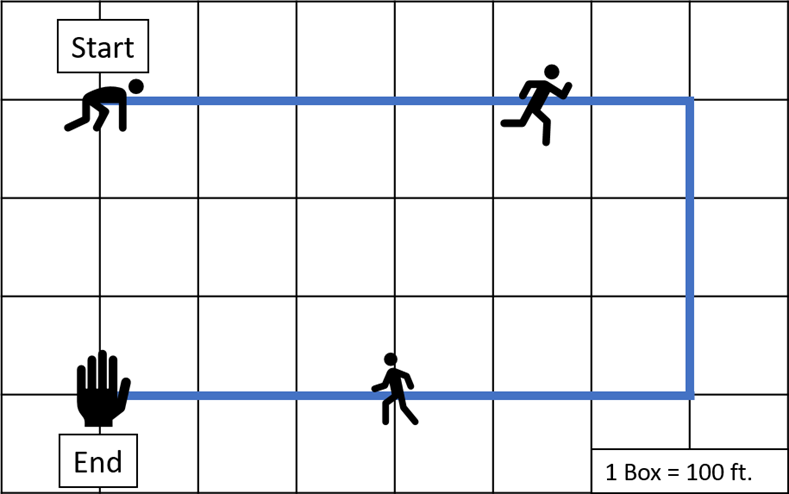

## Coding The Model

In this example, latitude and longitude have been stored into variable names *lat* and *lon* respectively. The first step in solving this is to declare a couple of variables in which the first will be the circumference of the earth in miles. The next variable is the total distance traveled which will be set to zero for now and explained why later.

earthCirc = 24901;
totaldis = 0;

To solve this problem, calculations will have to be repeated several times in a loop. Because of this we use a function called a for loop which will repeat for a specified amount of times. In this case, we want to have it run until the end of our vector of data. The ‘length’ command can be used to determine the number of elements in a vector and therefore how many times we need to run the loop. When solving for the difference in position one position and the next position are used at the same time. Because of this we need to stop one before the end of the vector as seen below. If this isn't done we will get an error because we will be trying to acces data from outside of the vector.

for i = 1: (length(lat)-1)

Now we save the first position and the second position into variables. We will do this using the variable *i* from above. This variable is a vector from 1 to the end of our latitude vector which can be used to index the latitude and longitude vectors.

lat1 = lat(i);     %The first latitude
lat2 = lat(i+1);   %The second latitude
lon1 = lon(i);
lon2 = lon(i+1);

Thankfully for us MATLAB has a command to solve for distance given latitude and longitude. This will give us the difference in degrees which we will then turn into length by creating equivalent fractions as such.


$$\frac{\textrm{traveledDistance}}{\textrm{earth'sCircumference}}=\frac{\textrm{degreesTraveled}}{\textrm{earth'sDegrees}}\;$$


From this we solve for *traveledDistance*. We will use 360 for *earth’sDegrees *because that is the total number of degrees in a circle. While the earth is not a perfect circle this will still be a good estimation

diff = distance(lat1, lon1, lat2, lon2);
dis = (diff/360)*earthCirc;

Now we add up the distance and store it into the total distance variable. What this code will do is take the previous total distance and add the distance just calculated onto it. We declared the total distance variable before the loop so that we could use it on the first iteration of the loop because you can't add something to nothing. With this we’ve calculated everything that we needed to within the for loop and must close the loop by using the *end *command.

totaldis = totaldis + dis;
end

Once the for loop has finished will have the total distance traveled. From here, we need to divide the total distance traveled by the stride to get the steps taken. For this example, we will use the average stride of 2.5ft. Since the total distance traveled in miles we will have to convert this into feet. 

stride = 2.5;    %Average stride (ft)
totaldis_ft = totaldis*5280;    %Converting distance from miles to feet
steps = totaldis_ft/stride;

An easy way to see the data that you are interested in is by priniting it to the screen once you find it. While you could also show it by removing the semicolon this way allows you to add text as well to specify exactly what data you are looking at.

disp(['The total distance traveled is: ', num2str(totaldis),' miles'])

The total distance traveled is: 0.4093 miles


disp(['You took ', num2str(steps) ' steps'])

You took 864.4514 steps


## Creating Graphics

There are many ways in which you can visualize data in MATLAB. Say we wanted to graph the acceleration data that we took earlier to compare how the X, Y and Z data compare against one another. We can do this using the plot command. The only problem with this command is plotting multiple data on the same graph the code can be messy in one line. Because of this we use the *hold on* command to continuously plot on the same graph. Don't forgot to also use *hold off* when you are done or else everything you plot will go on the same graph.

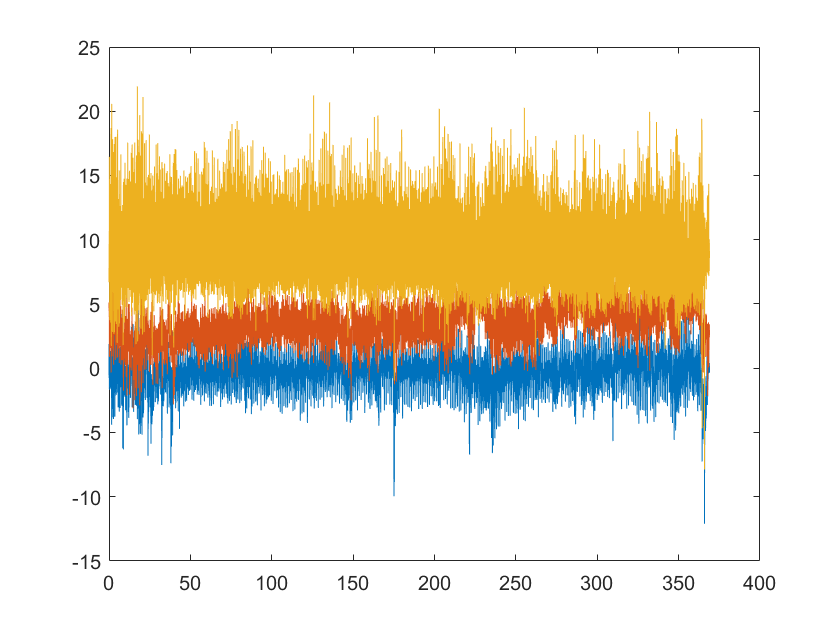

plot(accelTime,Xacc);
hold on;
plot(accelTime,Yacc); 
plot(accelTime,Zacc);
hold off

While there is nothing wrong with the graph that we just made it is very difficult to differentiate between the lines. This is because there is so much data being graphed in such a small window. Because of this we will want to zoom in on the graph in order to see any trends between the different data lines. To do this a limit is set on the x axis so that we can look at the first 50 seconds of data.

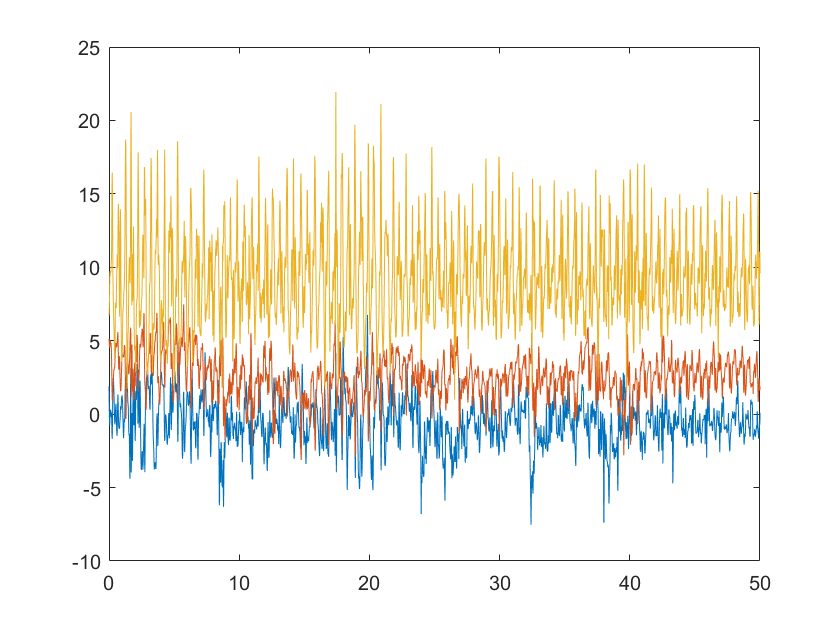

plot(accelTime,Xacc);
hold on;
plot(accelTime,Yacc); 
plot(accelTime,Zacc);
xlim([0 50])
hold off

While this isn't the prettiest graph this still gives a better idea as to what each data line looks like. Now we need to add labels onto the graph so that we may know which line corresponds to which set of data. We will also want to add a title and labels onto this graph so that someone who doesn't know what this data is can read the graph without looking at the code.

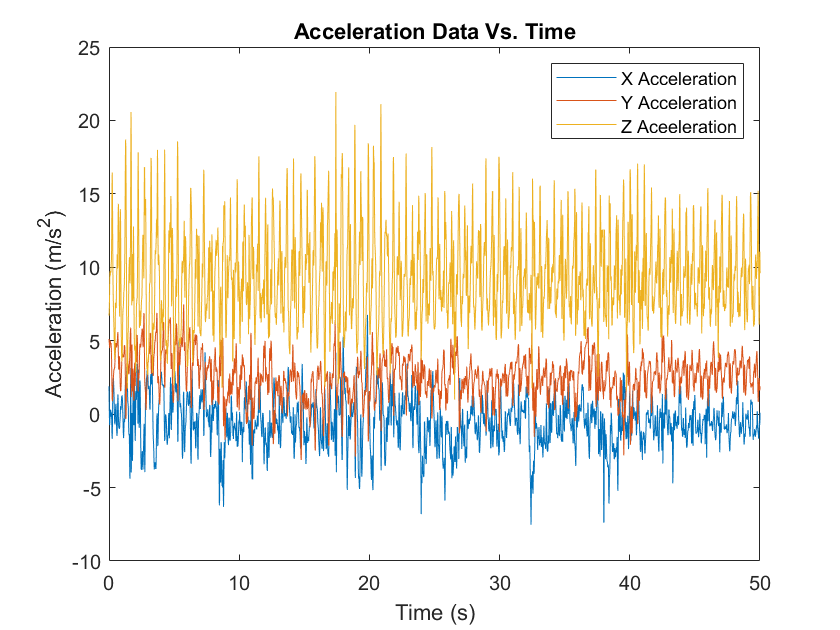

plot(accelTime,Xacc);
hold on;
plot(accelTime,Yacc); 
plot(accelTime,Zacc);
xlim([0 50])
legend('X Acceleration','Y Acceleration','Z Aceeleration');
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)');
title('Acceleration Data Vs. Time');
hold off

With this we now have the ideal graph that we're looking for. There are many other things that we can add and edit on this graph. One important tool when it comes to graphing is called the LineSpec or line specification. This allows us to be able to edit the properties of the graph's data. For example, if we wanted to plot the X acceleration by itself but only each data point without a line connecting them with the LineSpec.

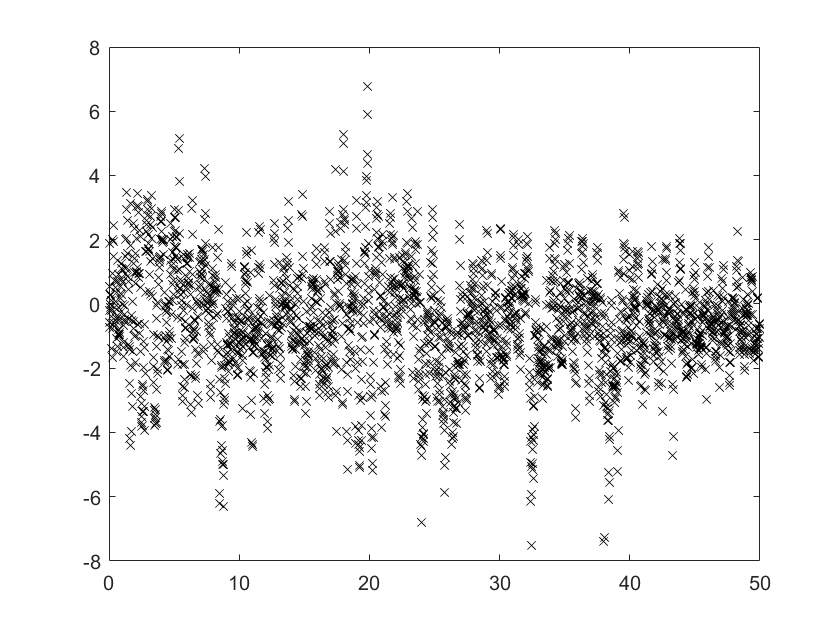

plot(accelTime,Xacc, 'kx');
xlim([0 50])

In this example the *k* refers to the color which is black and the *x* refers to the marker type. There are many other options that can be changed and if you want to look are what other options try using the command 'doc LineSpec' in the command window and clock on the first entry.